clear
load data2.mat
n=length(data.CzasLokalnyUTC0000)

n = 516459

data.CzasLokalnyUTC0000(1:4)

ans = 4×1 datetime array
   NaT                
   15/03/2024 11:00:09
   15/03/2024 11:00:14
   15/03/2024 11:00:19


data.CzasLokalnyUTC0000(n-3:n)

ans = 4×1 datetime array
   16/04/2024 08:49:27
   16/04/2024 08:49:32
   16/04/2024 08:49:37
   NaT                


From time vector:

T=5; %[s]
fs=1/T; %[Hz]
t=T*(1:n-1);
Wlot=0.1*data.Wlot;
X=Wlot;
compressor=data.Kompresor1;
[x,nan_indices]  = GetRidOfNans(X);

## Interpolation

x_interp = InterpolateData(x,[-5,0],t);

## Remooving anomalies

anomaly_locs=compressorCycles(compressor);
features = FeatureExtract(x_interp,anomaly_locs);
f1=zeros(1,length(anomaly_locs)-1);
for i=1:length(anomaly_locs)-1
    f1(i)=anomaly_locs(i+1)-anomaly_locs(i);
end
anomaly_locs=anomaly_locs(2:end);
fridge_air_temp_p2p=features(1,:)-features(2,:);
indexContainer=cell(1);
indexContainer{1}=[];
set=1;
figure
TF = isoutlier(fridge_air_temp_p2p);
for i=2:length(features)
    
    if (TF(i)==0)
        indexContainer{set}=[indexContainer{set},anomaly_locs(i-1):anomaly_locs(i)];
    else
        if TF(i-1)==0
            set=set+1;
            indexContainer{set}=[];
        end
    end
end

## Setting proper index container Convergence Analysis:

N_badResults   = nan(1,5);
tot_timeUnderConsideration = nan(1,5);
for Min_dataLength = 1:5

    %–– build the cell array of valid indices
    usableDataIndex = {};
    usableDataIndex_length = 0;
    set = 1;
    for i = 1:length(indexContainer)
        if length(indexContainer{i}) > 60*60*Min_dataLength*0.5*fs
            usableDataIndex{set} = indexContainer{i};
            usableDataIndex_length = usableDataIndex_length + length(indexContainer{i});
            set = set + 1;
        end
    end

    %–– if nothing survived, skip the analysis and record zeros
    if isempty(usableDataIndex)
        N_badResults(Min_dataLength)         = 0;
        tot_timeUnderConsideration(Min_dataLength) = 0;
        continue
    end

    %–– otherwise do your normal analysis
    results = analyzeCompressorSegments( ...
        t, x_interp, compressor, usableDataIndex, ...
        'MinPeakProminence', 0.8, ...
        'MinPeakDistance',   0.17, ...
        'PlotResults',       false);

    pctErrorVector = nan(1,length(results));
    for i = 1:length(results)
        pctErrorVector(i) = results(i).stats.pctError;
    end
    idx_badResults = find(abs(pctErrorVector) > 10);
    N_badResults(Min_dataLength) = length(idx_badResults);
    tot_timeUnderConsideration(Min_dataLength) = usableDataIndex_length;
end

--- Segment 1 ---
Measured ON-time   = 0.2 h
Predicted ON-time  = 0.2 h
Difference         = -24.0 s (-3.5%)

--- Segment 2 ---
Measured ON-time   = 0.1 h
Predicted ON-time  = 0.1 h
Difference         = +6.0 s (1.9%)

--- Segment 3 ---
Measured ON-time   = 0.2 h
Predicted ON-time  = 0.2 h
Difference         = -13.0 s (-2.2%)

--- Segment 4 ---
Measured ON-time   = 0.5 h
Predicted ON-time  = 0.5 h
Difference         = +23.0 s (1.3%)

--- Segment 5 ---
Measured ON-time   = 0.5 h
Predicted ON-time  = 0.5 h
Difference         = -7.0 s (-0.4%)

--- Segment 6 ---
Measured ON-time   = 0.0 h
Predicted ON-time  = 0.0 h
Difference         = +9.0 s (9.9%)

--- Segment 7 ---
Measured ON-time   = 0.0 h
Predicted ON-time  = 0.0 h
Difference         = +17.0 s (20.5%)

--- Segment 8 ---
Measured ON-time   = 0.1 h
Predicted ON-time  = 0.1 h
Difference         = +23.0 s (5.4%)

--- Segment 9 ---
Measured ON-time   = 0.1 h
Predicted ON-time  = 0.1 h
Difference         = +7.0 s (2.6%)

--- Segment 10 ---


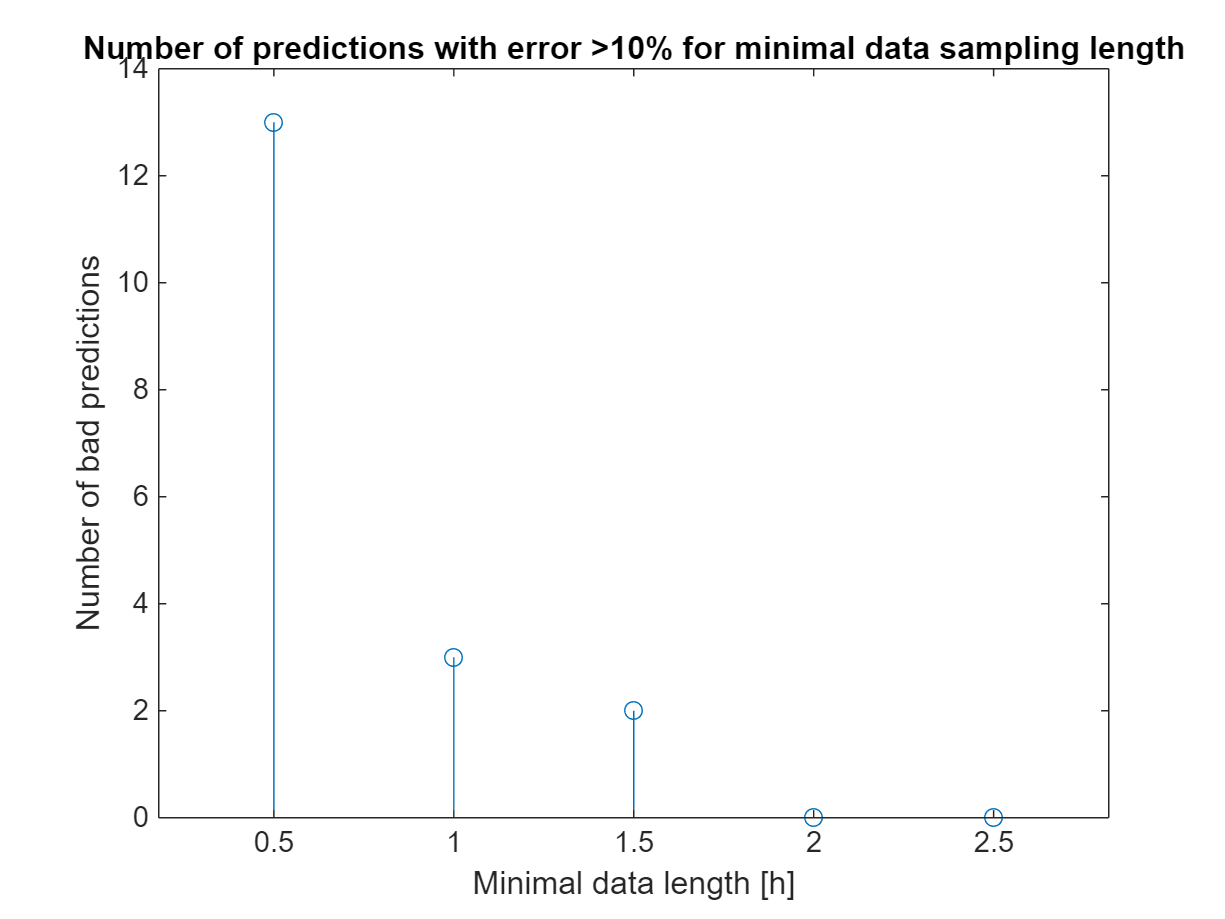

stem((1:5)*0.5,N_badResults);
xlabel('Minimal data length [h]')
ylabel('Number of bad predictions')
title('Number of predictions with error >10% for minimal data sampling length')

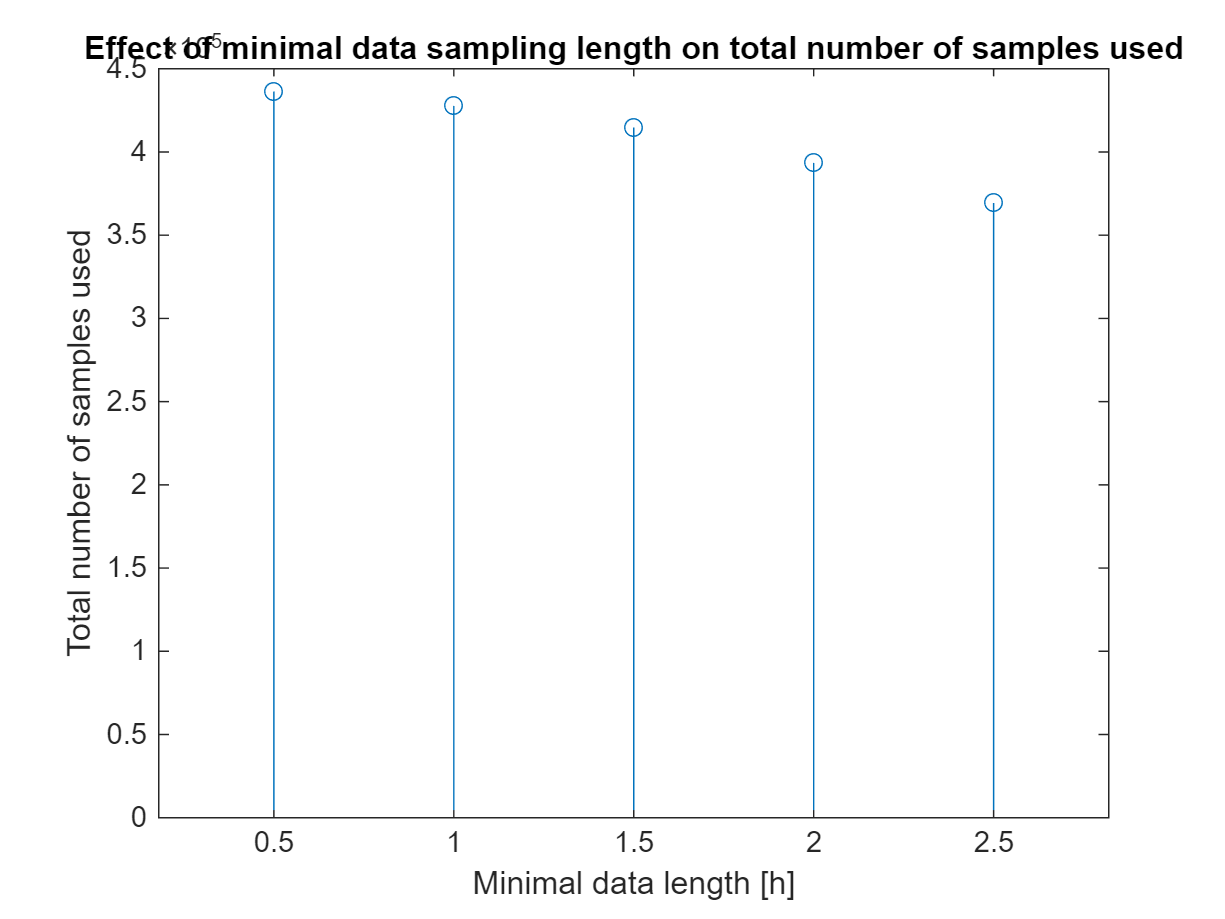

stem((1:5)*0.5,tot_timeUnderConsideration);
xlabel('Minimal data length [h]')
ylabel('Total number of samples used')
title('Effect of minimal data sampling length on total number of samples used')

We can see that using 2h gives us the least amout of bad results with the longest total length of signal under consideration

### Setting proper index container from Minimal data length convergence analysis:

set=1;
usableDataIndex_length = 0;

clear usableDataIndex
for i = 1:length(indexContainer)
    if length(indexContainer{i})>60*60*2*fs
        usableDataIndex{set}=indexContainer{i};
        usableDataIndex_length = usableDataIndex_length + length(indexContainer{i});
        set=set+1;
    end
end

## Peak-Valleys detection based compressor prediction:

results = analyzeCompressorSegments( ...
    t, x_interp, compressor, usableDataIndex, ...
    'MinPeakProminence', 0.8, ...
    'MinPeakDistance', 0.17, ...
    'PlotResults', false);

--- Segment 1 ---
Measured ON-time   = 0.2 h
Predicted ON-time  = 0.2 h
Difference         = -24.0 s (-3.5%)

--- Segment 2 ---
Measured ON-time   = 0.2 h
Predicted ON-time  = 0.2 h
Difference         = -13.0 s (-2.2%)

--- Segment 3 ---
Measured ON-time   = 0.5 h
Predicted ON-time  = 0.5 h
Difference         = +23.0 s (1.3%)

--- Segment 4 ---
Measured ON-time   = 0.5 h
Predicted ON-time  = 0.5 h
Difference         = -7.0 s (-0.4%)

--- Segment 5 ---
Measured ON-time   = 0.5 h
Predicted ON-time  = 0.5 h
Difference         = +28.0 s (1.5%)

--- Segment 6 ---
Measured ON-time   = 0.2 h
Predicted ON-time  = 0.2 h
Difference         = +8.0 s (1.0%)

--- Segment 7 ---
Measured ON-time   = 0.2 h
Predicted ON-time  = 0.2 h
Difference         = -5.0 s (-0.6%)

--- Segment 8 ---
Measured ON-time   = 0.2 h
Predicted ON-time  = 0.2 h
Difference         = -13.0 s (-1.7%)

--- Segment 9 ---
Measured ON-time   = 0.2 h
Predicted ON-time  = 0.2 h
Difference         = +1.0 s (0.1%)

--- Segment 10 ---

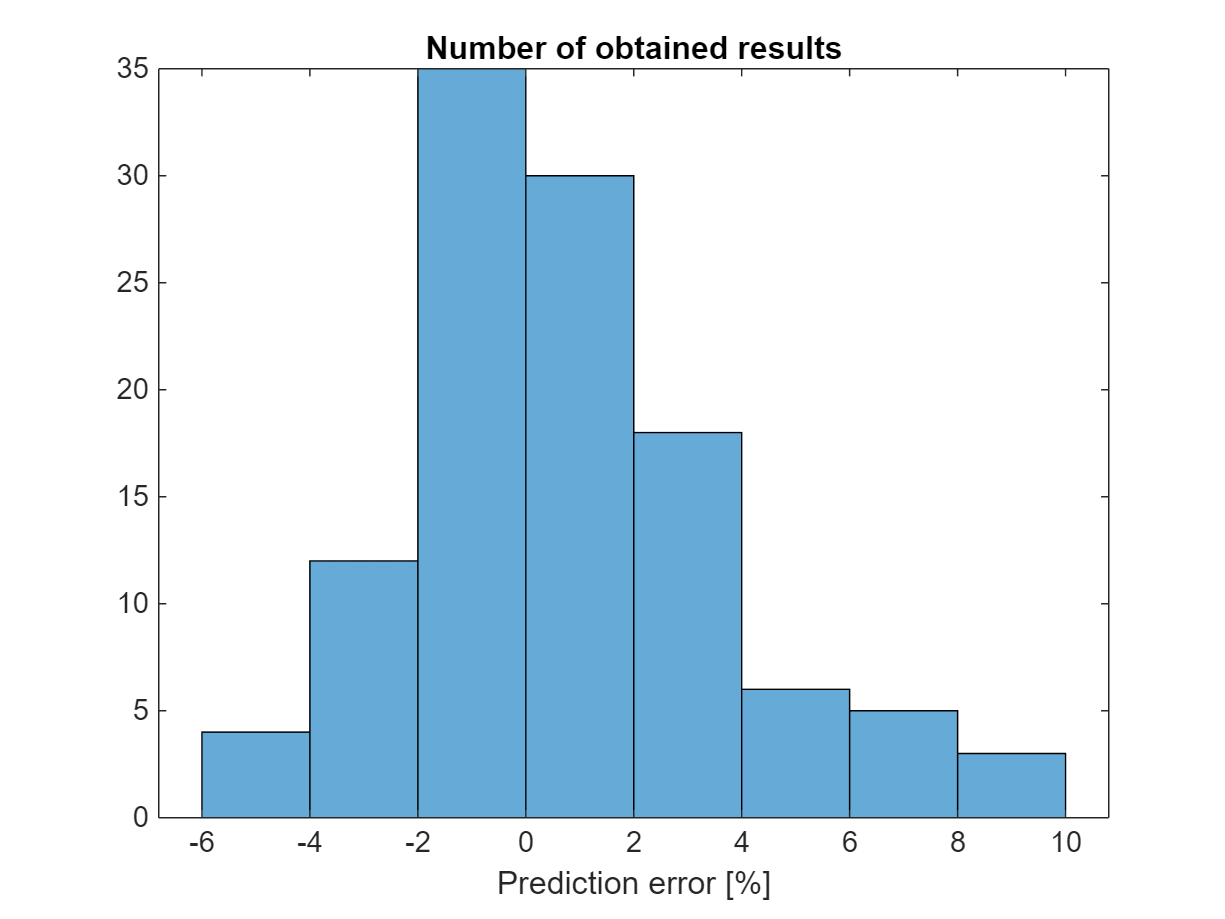

pctErrorVector=nan(1,length(results));
for i=1:length(results)
    pctErrorVector(i)=results(i).stats.pctError;
end
histogram(pctErrorVector)
xlabel('Prediction error [%]')
title('Number of obtained results')

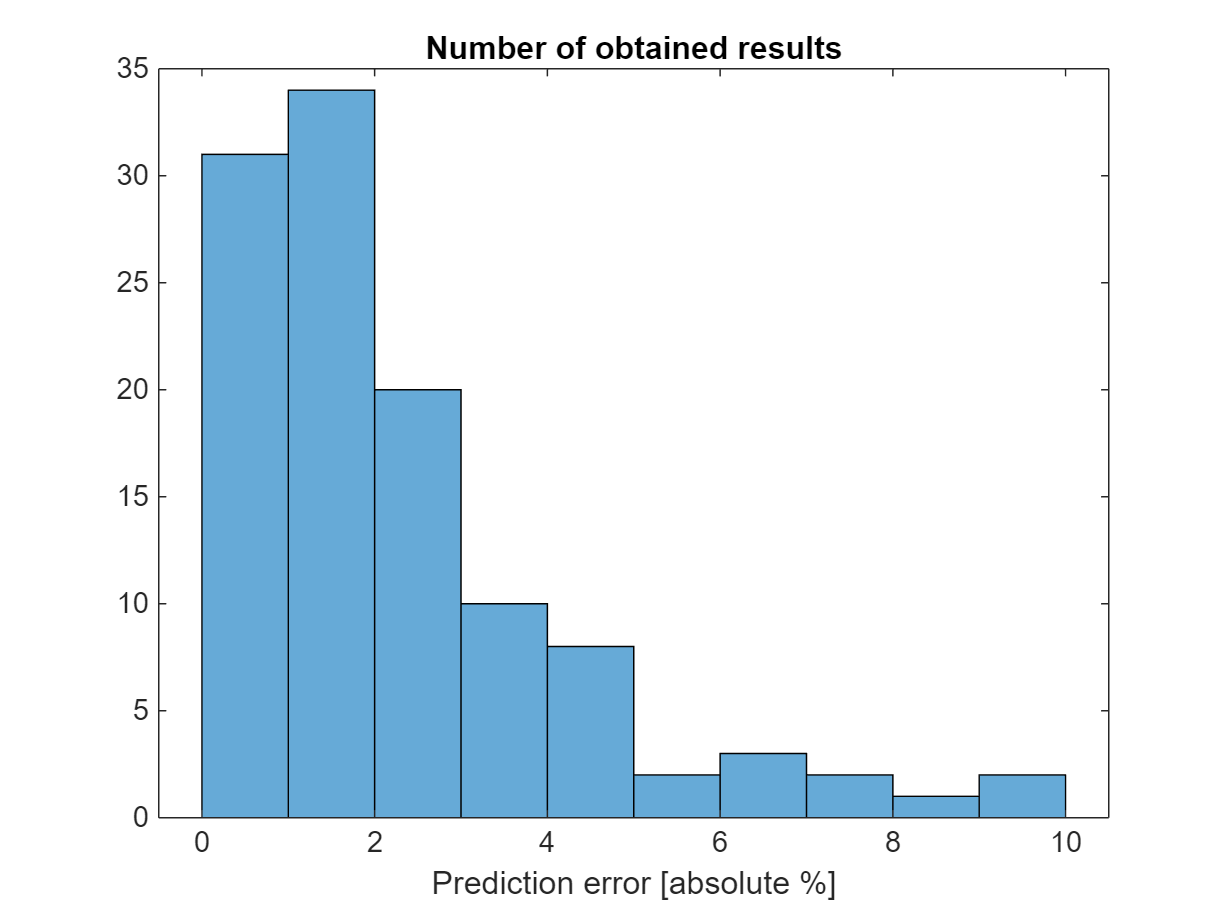

histogram(abs(pctErrorVector))
xlabel('Prediction error [absolute %]')
title('Number of obtained results')

idx_badResults = find(abs(pctErrorVector) > 10); 
results_bad=analyzeCompressorSegments( ...
    t, x_interp, compressor, usableDataIndex(idx_badResults), ...
    'MinPeakProminence', 0.8, ...
    'MinPeakDistance', 0.17, ...
    'PlotResults', false);

No results with error > 10%

fprintf('\n=== Data Quality / Error Summary ===\n');


=== Data Quality / Error Summary ===


fprintf('Mean Absolute Percentage Error (MAPE):   %.4f\n',  mean(abs(pctErrorVector)));

Mean Absolute Percentage Error (MAPE):   2.2965


fprintf('Length of usableDataIndex array [h]:        %d\n',     usableDataIndex_length/(60*60*fs));

Length of usableDataIndex array [h]:        5.464236e+02
